% 测试差分方法
clear;clc;
fd = FD(2);
% x = -pi:0.1:pi;
% u = [sin(x);cos(x)];
% v = [cos(x);-sin(x)];
% u_x = u * 0;
% for i = 1:2
%     u_x(i,:) = fd.computeDerivative(u(i,:),0.1);
% end
% plot(x,u_x,'-x',x,v,'--')




% % 测试 RK
% s_x = 0;
% e_x = 2*pi;
% n = 20; % 网格点数量
% x = linspace(s_x, e_x, n);
% t = 0;
% h = 0.01;% 时间间隔
% u = sin(x); % u_0
% 
% d_x = (e_x - s_x) / n; % 空间间隔
% 
% T(1) = t;
% L_2_eorr(1) = 0;
% 
% % 测试差分
% % plot(x, u_x(u, d_x))
% 
% k = 1;
% % 三阶rungge kutta
% rk = RK;
% Q = @(u) -fd.computeDerivative(u,d_x);
% while t <= 1
%     k = k + 1;
%     if mod(k,100) == 0
%         fprintf('计算第%d步\n',k);
%     end
% 
%     u = rk.rk3(u,Q,h);
%     
%     u_e = sin(x-t);
%     t = t + h;
%     l_2_error = norm(u_e - u);
%     plot(x,u,'-h',x,u_e,'-*')
%     ylim([-1 1])
%     xlim([s_x e_x])
%     title(sprintf('T = %.2ds, L_2 ERORR = %.2d',t,l_2_error))
%     legend('差分','解析');
%     pause(0.1)
% 
% end

clear;clc;
dt = 0.001;
dx = 0.005

dx = 0.0050

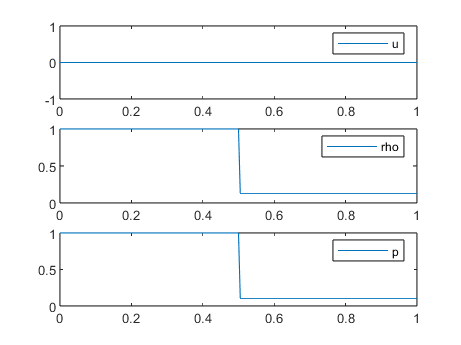

rk = RK;
fvs = FVS;
fd = FD(4);
sod = MySod(dx,0,1,dt,1.4);
sod.build(0,1,1,0,0.125,0.1);
sod.show(); % 展示初始条件

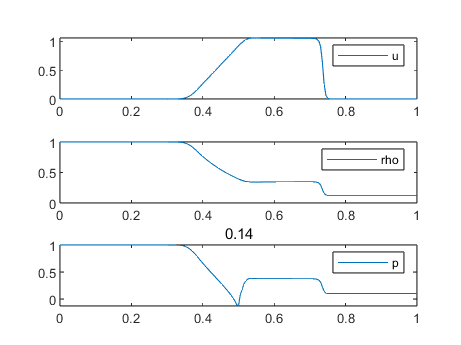

% 采用差分方法推进到0.14s
for i = 0:dt:0.14
    sod.timeStep(fd, rk);
    sod.show();
    title(i)
    pause(dt);
end

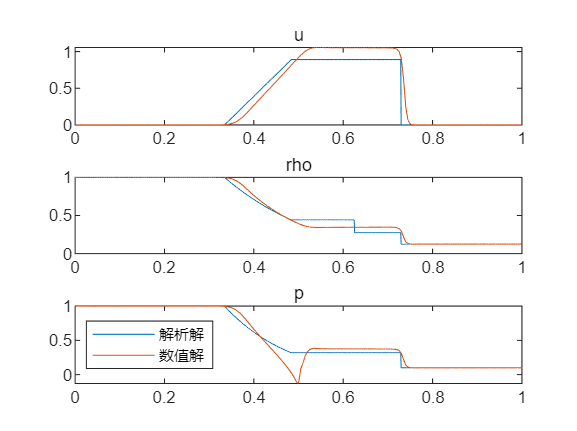

% 解析解
ref = analytic_sod(0.14);
ref.x = ref.x + 0.5; % 解析解中默认的坐标是[-0.5,0.5],需要平移

% 与解析解对比
subplot(311)
plot(ref.x,ref.u,sod.x,sod.u)
title('u')

subplot(312)
plot(ref.x,ref.rho,sod.x,sod.rho)
title('rho')

subplot(313)
plot(ref.x,ref.P,sod.x,sod.p)
title('p')

legend('解析解','数值解',Location='best')